clear

A = [0 -1; 1 0];
x0 = [1; 0];

% numerical solution
T = 10;
N = 40;
disp("N="+N);

N=40


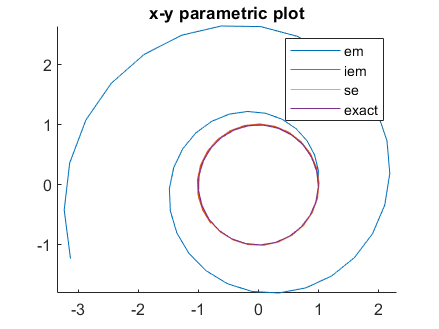

sol1 = EMsolver(A, x0, T, N);
sol2 = IEMsolver(A, x0, T, N);
sol3 = SEsolver(A, x0, T, N);

% analytical solution
t = 0:T/N:T;
sol = [cos(t); sin(t)];
figure
hold on
title("x-y parametric plot");
plot(sol1(1, :), sol1(2, :));
plot(sol2(1, :), sol2(2, :));
plot(sol3(1, :), sol3(2, :));
plot(sol(1, :), sol(2, :));
legend("em", "iem", "se", "exact");
axis equal

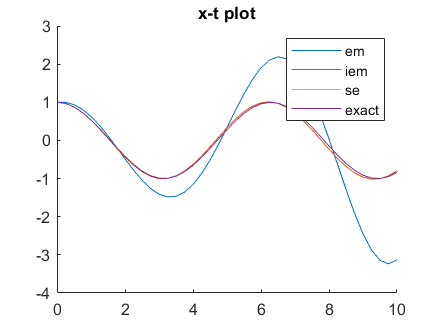


figure
hold on
title("x-t plot");
plot(t, sol1(1, :));
plot(t, sol2(1, :));
plot(t, sol3(1, :));
plot(t, sol(1, :));
legend("em", "iem", "se", "exact");

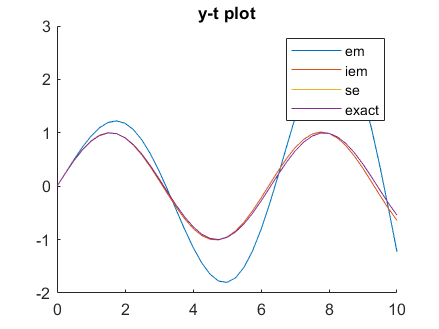


figure
hold on
title("y-t plot");
plot(t, sol1(2, :));
plot(t, sol2(2, :));
plot(t, sol3(2, :));
plot(t, sol(2, :));
legend("em", "iem", "se", "exact");

Plot the error

N1 = 10;
N2 = 400;
Ns = N1:N2;
err1 = zeros(1, N2-N1+1);
err2 = zeros(1, N2-N1+1);
err3 = zeros(1, N2-N1+1);
for N = N1:N2
    t = 0:T/N:T;
    sol = [cos(t); sin(t)];
    sol1 = EMsolver(A, x0, T, N);
    err1(N-N1+1) = rmse(sol, sol1);
    sol2 = IEMsolver(A, x0, T, N);
    err2(N-N1+1) = rmse(sol, sol2);
    sol3 = SEsolver(A, x0, T, N);
    err3(N-N1+1) = rmse(sol, sol3);
end
figure
hold on
target_err = 0.1;
disp("em N=" + find(err1<target_err, 1, 'first'));

em N=214


disp("iem N=" + find(err2<target_err, 1, 'first'));

iem N=18


disp("se N=" + find(err3<target_err, 1, 'first'));

se N=1


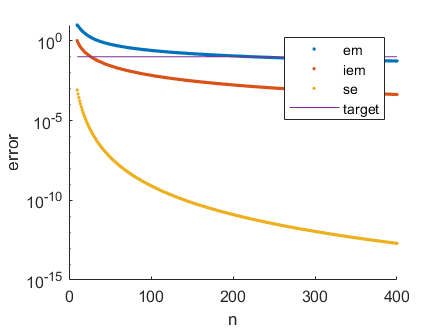

plot(Ns, err1, '.');
plot(Ns, err2, '.');
plot(Ns, err3, '.');
plot(Ns, ones(size(Ns))*target_err);
xlabel("n");
ylabel("error");
legend("em", "iem", "se", "target");
set(gca, 'YScale', 'log');

Part 2 - earthquake building

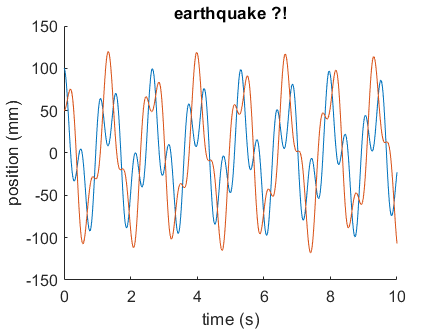

clear

k1 = 4.66;  % kN/mm
k2 = 4.66;
m1 = 0.0917;  % e6 kg
m2 = 0.0765;

% [x1 x1' x2 x2']
% m1 a1 = -k1 x1 - k2 (x1 - x2)
% m2 a2 = -k2 (x2 - x1)
A = [0 1 0 0;
     [-k1-k2 0 k2 0]/m1;
     0 0 0 1;
     [k2 0 -k2 0]/m2
    ];
x0 = [100 0 50 0]; % mm
N = 1000;
T = 10.0;
dt = T/N;
ts = 0:dt:T;
sols = SEsolver(A, x0, T, N);
figure
hold on
title("earthquake ?!");
plot(ts, sols(1, :), '-');
plot(ts, sols(3, :), '-');
xlabel("time (s)");
ylabel("position (mm)");

This morning's physics midterm

Two carts with masses 20kg and 35kg are connected by a 1000N/m spring and are initually at rest. You push the 20kg cart toward the 35kg cart with a 10N force. Find the accelerations of the carts when the spring is at its maximum compression.

clear

% x1, x1', x2, x2', 1
F = 10;
m1 = 20;
m2 = 35;
k = 1000;
L = 12.345;  % length of the spring??

% a1 = (F+k(x2-x1-L))/m1
% a2 = -k(x2-x1-L)/m2
A = [0, 1, 0, 0, 0;
     [-k, 0, k, 0, F-k*L]/m1;
     0, 0, 0, 1, 0;
     [k, 0, -k, 0, k*L]/m2;
     0, 0, 0, 0, 0];
x0 = [0, 0, L, 0, 1];
T = 2;
N = 1000;
t = 0:T/N:T;
sol = SEsolver(A, x0, T, N);
dsoldt = A*sol;
dL = sol(3, :)-sol(1, :) - L;
a1 = dsoldt(2, :);
a2 = dsoldt(4, :);
[mindL, mini] = min(dL);
disp("a1=" + a1(mini));

a1=-0.13636


disp("a2=" + a2(mini));

a2=0.36364


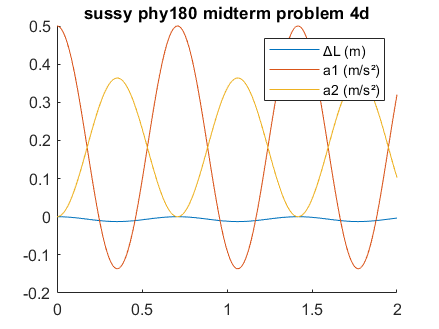


figure
hold on
title("sussy phy180 midterm problem 4d");
plot(t, dL);
plot(t, a1);
plot(t, a2);
legend("ΔL (m)", "a1 (m/s²)", "a2 (m/s²)");


$$x_1 = x_0 + \frac{dx}{dt} \Delta t + \frac{1}{2}\frac{d^2x}{dt^2} \Delta t^2 + \frac{1}{6}\frac{d^3x}{dt^3} \Delta t^3 + O(\Delta t^4)$$



$$\frac{dx}{dt} = Ax$$



$$\frac{d^2x}{dt^2} = \frac{d}{dt}Ax = A\frac{dx}{dt} = A^2x$$



$$\frac{d^n x}{dt^n} = A^n x$$


$\displaystyle x(t) = \left(\sum_{k=0}^{\infty} \frac{1}{k!}A^k (t-t_0)^k\right) x_0$ ??

Forward Euler solver


$$x_1 = x_0+Ax_0\Delta t = x_0 + \frac{dx}{dt}\Delta t$$


Error: $\frac{d^2x}{dt^2}\Delta t^2 + O(\Delta t^3)$

function [sol] = EMsolver(A, x0, T, N)
    dt = T/N;
    t = 0:dt:T;
    sol = NaN(length(A), length(t));
    sol(:, 1) = x0;
    for k = 2:length(t)
        sol(:, k) = sol(:, k-1) + A*sol(:, k-1)*dt;
    end
end

Improved Euler solver


$$x_1' = x_0 + Ax_0\Delta t$$



$$x_1 = x_0 + \frac{1}{2}A\left(x_0+x_1'\right)\Delta t = x_0 + \frac{1}{2}\left(2Ax_0+A^2x_0\Delta t\right)\Delta t = x_0 + Ax_0\Delta t + \frac{1}{2}A^2x_0\Delta t^2$$


Error: $\frac{1}{6}\frac{d^3x}{dt^3} \Delta t^3 + O(\Delta t^4)$

function [sol] = IEMsolver(A, x0, T, N)
    dt = T/N;
    t = 0:dt:T;
    sol = NaN(length(A), length(t));
    sol(:, 1) = x0;
    for k = 2:length(t)
        x1 = sol(:, k-1) + A*sol(:, k-1)*dt;
        sol(:, k) = sol(:, k-1) + A*(sol(:, k-1)+x1)/2*dt;
    end
end

Midpoint solver


$$x_m = x_0 + \frac{1}{2} Ax_0\Delta t$$



$$x_1 = x_0 + Ax_m\Delta t = x_0 + Ax_0\Delta t+\frac{1}{2}A^2x_0\Delta t^2$$


Identical to Improved Euler Solver for linear differential equations.

function [sol] = MPsolver(A, x0, T, N)
    dt = T/N;
    t = 0:dt:T;
    sol = NaN(length(A), length(t));
    sol(:, 1) = x0;
    for k = 2:length(t)
        xm = sol(:, k-1) + 0.5*A*sol(:, k-1)*dt;
        sol(:, k) = sol(:, k-1) + A*xm*dt;
    end
end

Series expansion solver

function [sol] = SEsolver(A, x0, T, N)
    dt = T/N;
    t = 0:dt:T;
    sol = NaN(length(A), length(t));
    sol(:, 1) = x0;
    % construct M
    I = eye(length(A));
    M = I;
    A1 = I;
    for i = 1:6
        A1 = A1*A*dt/i;
        M = M + A1;
    end
    % steps
    for k = 2:length(t)
        sol(:, k) = M * sol(:, k-1);
    end
end

Root mean squared error

function [e] = rmse(x1, x2)
    e = sqrt(mean((x2-x1).^2, "all"));
end